## 1D FEM Sample Model

% Sloution Benchmark
u  = @(x) [sin(x) ;  cos(x)] ;
Du = @(x) [cos(x) ; -sin(x)] ; 

% System Settings
m  = 2 ;  % number of dependent variables
A1 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
A0 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
f  = @(x) [1 ; 1] ;
g  = @(x) sin(x) + cos(x)    ;
ab = [ 0 , pi ] ;                 % ab = [ a , b ] domain

% Construct the model
model = Collocation1D(m, ab);
model.fitInterior(A1,A0,f,2)
model.fitBoundary([],@(x) [1,1],g,1)
model.fitTrueSol(u, Du)

% Discretization
n = 10; %50 ;                         % n global vertices
model.linear_discretize(n)

% Points Selection
rng(42) ;  % random seed
h = model.gm.Mesh.MinElementSize;
k = 10

k = 10

interior_points = linspace(ab(1), ab(2), k*n) ; % interior points
boundary_points = ab ; % boundary points

% System assemble
Lambda = diag(h.^(-3/2)*ones(1,1)) ;       % square(weights) for BC
[B_Omega, d_Omega, ~] = model.Assemble_B_Omega(interior_points) ;
[B_Gamma, d_Gamma, ~] = model.Assemble_B_Gamma(boundary_points, Lambda) ;
B = [B_Omega ; B_Gamma] ; d = [d_Omega ; d_Gamma];

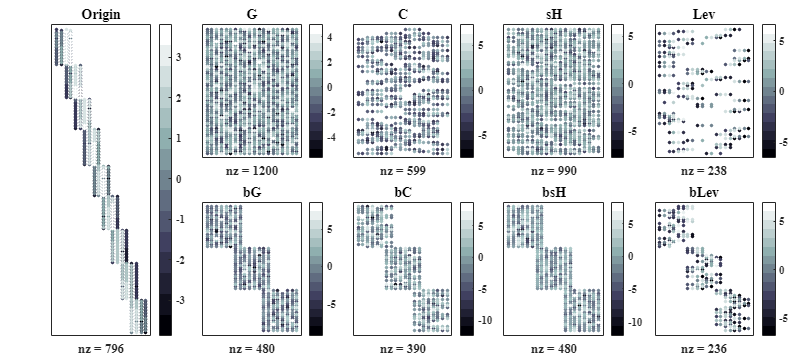

addpath('./Skechers/');
data = cell(1,10);
[mB,nB] = size(B_Omega); mS = 3*nB; num_coworker = 3;

for i = 1:10
    switch i
        case 1
            continue
        case 2
            SB = sketching(mS, B_Omega, 'Gaussian');
        case 3
            SB = sketching(mS, B_Omega, 'Hashing', {1, 'Regular'});
        case 4
            s = ceil(log(nB));
            SB = sketching(mS, B_Omega, 'Hashing', {s, 'Regular'});
        case 5
            [lev_score, ~, ~] = leverageScore(B_Omega,'Exact','svd');
            p = lev_score./sum(lev_score);
            SB = sketching(mS, B_Omega, 'Levscore', p);
        case 6
            continue
        case 7
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Gaussian');
        case 8
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {1, 'Regular'});
        case 9
            s = ceil(log(nB));
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {s, 'Regular'});  
        case 10
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Levscore', {'Exact','svd'});
    end
    data{i} = SB;
end


figure; set(gcf,'position',[0, 0, 1000, 450]); t = tiledlayout(2,5); 
errtitles = {'Origin', 'G', 'C', 'sH',  'Lev',...
             [], 'bG', 'bC', 'bsH',  'bLev'};
hY1 = [1,2]; hY2 = [2,2];

for i = 1:10

    if i ~= 1 && i ~= 6
        nexttile(i)
        cspy(data{i},'ColorMap','bone');
        ylim([-hY1(1), size(data{i},1)+hY1(2)]); yticks([]);
    elseif i == 1
        nexttile(1,[2,1])
        cspy(B_Omega,'ColorMap','bone');
        ylim([-hY2(1), size(B_Omega,1)+hY2(2)]); yticks([]);
    else
        continue
    end

    box on
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    title(errtitles{i},'fontweight','bold','FontSize',13);
    xlim([0, size(B_Omega,2)+1]); xticks([]); 
    ax.XAxisLocation = 'bottom';
end

t.TileSpacing = 'compact';
t.Padding = 'compact';

## 2D FEM Sample Model

% Construct the model
m  = 3 ;  % number of dependent variables
t = pi/20 : pi/20 : 2*pi;
Omega = polyshape({1.5*cos(t), 0.5+0.5*cos(t), 0.5+0.2*cos(t), -0.6+0.3*cos(t)}, ...
                  {1.5*sin(t), 0.5*sin(t), 1+0.2*sin(t), -0.8+0.3*sin(t)});  % Omega
model = Collocation2D(m, Omega); 
model.gm.pdegplot(VertexLabels="on",EdgeLabels="on");

beta = 5 ; hmax=0.15 ;                    % mesh size, hmin=hmax/beta 
model.discretize(hmax, beta, 'linear');  % Discretization

if true 
    model.gm.pdemesh(); %(ElementLabels="on", NodeLabels="on") ;
    hold on
    edge = model.boundary_decompose();
    for i = 1:model.gm.NumEdges
        scatter(edge{i}(1:end-1,1), edge{i}(1:end-1,2), "filled")
    end
    hold off
    fprintf('%d Nodes (%d unknowns) and %d Elements generated', size(model.gm.Mesh.Nodes,2), ...
            size(model.gm.Mesh.Nodes,2)*m, size(model.gm.Mesh.Elements,2));
end

% Sample Equation
% Sloution Benchmark: poisson
u = @(x,y) [sin(x.^2 + y.^2);  2*x.*cos(x.^2 + y.^2); 2*y.*cos(x.^2 + y.^2)]; % u=[phi, v1, v2]

% System Settings
num_eq = 4;
A1 = @(x,y) [1,0,0; 0,0,0; 0,-1,0; 0,0,1];
A2 = @(x,y) [0,0,0; 1,0,0; 0,0,-1; 0,-1,0];
A0 = @(x,y) [0,-1,0; 0,0,-1; 0,0,0; 0,0,0];
ff = @(x,y) 4*cos(x.^2 + y.^2) - 4*(x.^2 + y.^2).*sin(x.^2 + y.^2);
f  = @(x,y) [0 ; 0; -ff(x,y); 0];

num_cond = 2;
B1 = [];
B2 = [];
B0 = @(x,y) [1,0,0; 0, model.boundary_normal([x,y], 2), -model.boundary_normal([x,y], 1)];
g1 = @(x,y) sin(x.^2 + y.^2);
g2 = @(x,y) model.boundary_normal([x,y]) * [-2*y.*cos(x.^2 + y.^2); 2*x.*cos(x.^2 + y.^2)];
g  = @(x,y) [g1(x,y); g2(x,y)];

% Construct the model
model.fitInterior(A1, A2, A0, f, num_eq);
model.fitBoundary(B1, B2, B0, g, num_cond);
model.fitTrueSol(u);

% Coordinates of the closed boundary nodes
rng(42) ;  % random seed
N_Gamma = 20000; % N_Gamma boundary points
N_loc = 30;   % N_loc points per element
sampled_boundary_nodes = model.gm.Mesh.Nodes(:,model.BoundaryNodeIDs)';
sampled_interior_nodes = model.sample_from_triangleMesh(model.gm.Mesh, N_loc);

N_Omega = size(sampled_interior_nodes, 1); N_Gamma = size(sampled_boundary_nodes, 1);
fprintf('N_Omega: %d, N_Gamma: %d, total: %d', N_Omega, N_Gamma, N_Omega + N_Gamma);
fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);

if true 
    model.gm.pdemesh();
    hold on
    scatter(sampled_interior_nodes(:,1), sampled_interior_nodes(:,2));
    scatter(sampled_boundary_nodes(:,1), sampled_boundary_nodes(:,2), "filled");
    hold off
end

% System assemble
Lambda = diag(10*ones(1,num_cond));     % square(weights) for BC
[B_Omega, d_Omega, N_Omega] = model.Assemble_B_Omega(sampled_interior_nodes);
[B_Gamma, d_Gamma, N_Gamma] = model.Assemble_B_Gamma(sampled_boundary_nodes, Lambda);
B = [B_Omega ; B_Gamma];  d = [d_Omega ; d_Gamma];
d(any(isnan(B), 2)) = []; B(any(isnan(B), 2), :) = [];

fprintf('N_Omega: %d, N_Gamma: %d, total: %d', N_Omega, N_Gamma, N_Omega + N_Gamma);
fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d', N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);
fprintf('num_eq: %d, num_unknown: %d, ratio m/n: %.2f', size(B,1), size(B,2), size(B,1)/size(B,2));
spy(B); c = B\d; model.C = model.reshape2mat(c); 
% save('./data/2DsktSample/2DsktSampleModel_small.mat', 'model');

sparsity = (1:10)/10 ;
time = zeros(100,10);
for i = 1:length(sparsity)
    for j = 1:100
        S = sprand(500,20,sparsity(i));
        f = @() qr(S);
        time(j,i) = timeit(f);
    end
end

figure ;
plot(log10(sparsity*1e4), log10(median(time)), '--o')
grid on

% Start from here
addpath('./Skechers/');
% load('./data/1DsktSample/1DsktSampleModel_small.mat');
load('./data/2DsktSample/2DsktSampleModel_small.mat');
B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; spy(B);
[mB, nB] = size(B); exact_problem.B = B; exact_problem.d = d;
[mBo, nBo] = size(B_Omega);

% [~, full_exact_problem_time] = solveLLS(full(B), d);
[exact_problem.sol, exact_problem.time, ...
exact_problem.sparsity, exact_problem.res] = solveLLS(B, d, 0.1);
exact_problem
skt_coe = 10;  mS = round(skt_coe * nB);



[lev_score1, ~, time1] = leverageScore(B_Omega,'Exact',[],'svd'); p1 = lev_score1/sum(lev_score1);
[lev_score2, ~, time2] = leverageScore(B_Omega,'Approx',[],'svd'); p2 = lev_score2/sum(lev_score2);
[lev_score3, ~, time3] = leverageScore(B_Omega,'Hashing_Approx',[],'svd'); p3 = lev_score3/sum(lev_score3);

[SBd, time_sketch, p, I] = blockEmbedding(mS, [B_Omega, d_Omega], 50, 'Levscore', {'Hashing_Approx','svd'});
SBd = [SBd; [B_Gamma, d_Gamma]];
[sol, time_solve, new_sparsity, ~] = solveLLS(SBd(:,1:end-1), SBd(:,end), 0.1);

spy(SBd(:,1:end-1));
new_sparsity
time_sketch
time_solve
time_total = time_sketch + time_solve
error = norm(sol-exact_problem.sol)
res = norm(B*sol-d)
plot(p)

num_worker = 25;
[mB, ~] = size(B); 
rowsPerWorker = floor(mB/num_worker);
rowsPerSubS = max([1,round(mS*rowsPerWorker/mB)]);
subSB = cell(num_worker,1); 
time = zeros(1,num_worker); 
i = 40;

if i < num_worker 
    subB = B((i-1)*rowsPerWorker+1:i*rowsPerWorker,:); 
else
    subB = B((i-1)*rowsPerWorker+1:end,:);
end

[~, cId] = find(subB); 
subCol = subB(:, unique(cId)); 
[mm,nn] = size(subCol); subColf = full(subCol);
[~,R,~] = qr(subCol,"econ","vector"); 

figure; spy(subB);
figure; spy(subCol);
figure; spy(R);

if mm > ceil(log(nn))
    s_per_col = ceil(log(nn));
else
    s_per_col = 2;
end

if mm > ceil(log(nn))*nn
    dd = nn*ceil(log(nn)); 
else
    dd = 2*nn;
end

S_1 = sHashing(s_per_col, dd, mm, 'Regular'); S1 = @(A) S_1*A; 
S2  = sHashing(s_per_col, ceil(2*log(mm)), nn, 'Regular');
tic; [lev_score, ~] = parforleverageScore(subCol, S1, S2', 'Approx', 'svd'); lev_time = toc

tic;
S = sketching_S(rowsPerSubS, subB, 'Levscore', lev_score/sum(lev_score)); subSB = S*subB;
skt_time = toc
% lev_time + skt_time

spy(subCol)


A = subColf;
tic;
[mm,nn] = size(A);
new_A = [];
p = [];
for j = 1:nn
    i = setdiff(find(A(:,j)),p);
    p = [p;i];
end
toc
% p = [];
% spy(subColf(962:2363,:))



S2 = S2';
A = subColf;
tic;
[~,S,V] = svdecon(S1(A));
time1 = toc

tic;
rank(S1(A));
time1 = toc

% tic;
% S = diag(S); 
% r = full(sum(S>1e-6)); 
% S_inv = sparse(1:r, 1:r, 1./S(1:r)); 
% R_inv = V(:,1:r)*S_inv; 
% X = R_inv*S2(1:r,:); 
% U_approx = A*X;
% time2 = toc
